imgs_3 = img_load("data/extracted_images/3");

'img_load' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/ariporad/OneDrive - Olin College of Engineering/QEA-Project1

Change the MATLAB current folder or add its folder to the MATLAB path.

imgs_4 = img_load("data/extracted_images/4");
imgs = [imgs_3; imgs_4];
imgs = imgs - mean(mean(imgs))

[V, D] = generate_eigenvectors(imgs, 64);

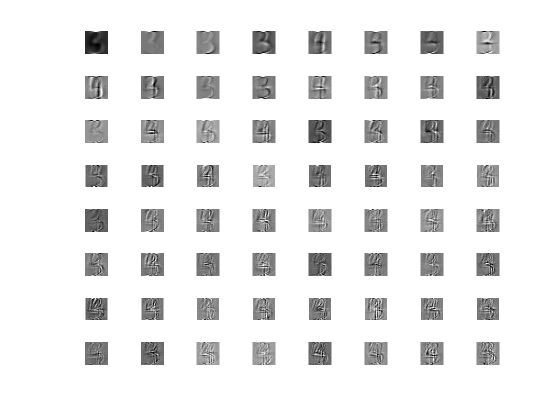

clf
subplot_size = ceil(sqrt(size(V, 2)));
for i = 1:size(V, 2)
    subplot(subplot_size, subplot_size, i);
    img_size = sqrt(size(V, 1));
    imagesc(reshape(V(:, i), [img_size img_size])); colormap('gray');
    axis equal;
    set(gca, 'visible', 'off');
end

test_data = img_load("test-data/3");
test_data = test_data - mean(mean(imgs));

train_data_projected = V'*imgs';
test_data_projected = V'*test_data';
rets = knnsearch(train_data_projected', test_data_projected')

rets =          545
       11120


img =    11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735


img_size = 45

img =    11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735 -243.1265 -243.1265   11.8735   11.8735   11.8735    8.8735   11.8735   11.8735    8.8735   11.8735   11.8735    7.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735
   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735    8.8735   11.8735   11.8735 -243.1265   11.8735   11.8735   11.8735   10.8735   10.8735   11.8735    9.8735   11.8735   11.8735   11.8735    7.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735
   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735  

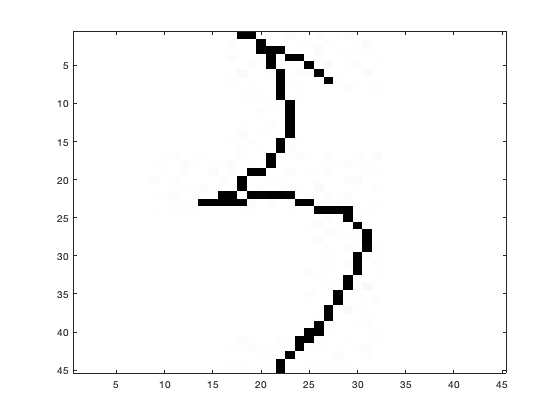

img =    11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735


img_size = 45

img =    11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   10.8735   11.8735   10.8735   11.8735    9.8735   11.8735 -242.1265   11.8735   11.8735   11.8735   10.8735   11.8735   11.8735   11.8735    8.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735
   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735    9.8735    8.8735   11.8735 -243.1265   11.8735   10.8735   11.8735    7.8735   11.8735    7.8735   11.8735   11.8735   10.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735
   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735   11.8735  

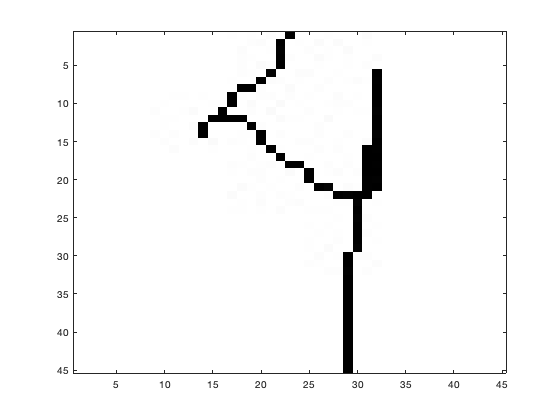

for i=1:length(rets)
    figure;
    img = imgs(rets(i), :)
    img_size = sqrt(length(img))
    img = reshape(img, [img_size img_size])
    imagesc(img); colormap('gray')
end